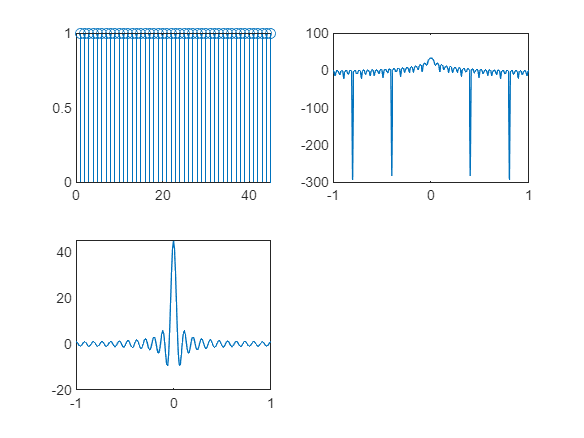

close all

M = 45;

win = ones(1,M);

figure
subplot(221), stem(win)

w = -pi:2*pi/200:pi;
W = sin(w*M/2) ./ sin(w/2);
W((length(w)+1)/2) = M;

subplot(223), plot(w/pi,W)

Wdb = 20*log10(abs(W));
subplot(222), plot(w/pi, Wdb)

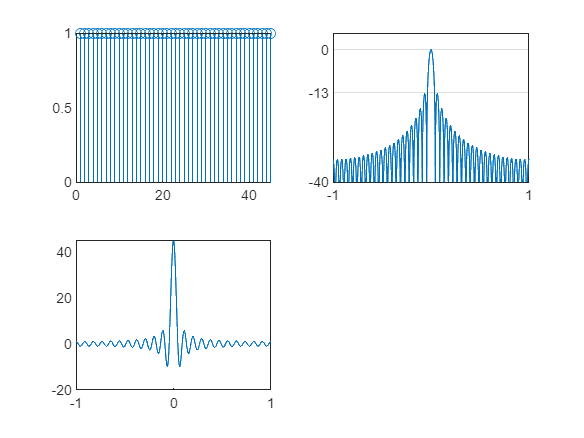

close all

M = 45;

win = ones(1,M);

figure
subplot(221), stem(win)

w = -pi:2*pi/1000: pi;
W = sin(w*M/2) ./ sin(w/2);

subplot(223), plot(w/pi,W)

Wdb = abs(W);
Wdb = Wdb/max(Wdb);
Wdb = 20*log10(abs(Wdb));
subplot(222), plot(w/pi, Wdb)
axis([-1 1 -40 5])
set(gca,'YTick', [-40 -13 0])
set(gca, 'XTick', [-1 1])
grid on